Rician

Rice factor K=1

clear
N=10^6; %number of samples
L=4; %number of paths
J=5; %number of different SNR
SNR=[1.26,2,3,5,10/1.26];
%bit error probability of QPSK
P_b=@(x) 1/2*erfc(sqrt(x/2));%(= qfunc(sqrt(x)))
% g_I,g_Q are iid Gaussian random variables with mean=1 variance=N_0
% use g_I and g_Q to generate desired Ricean random variable a and phase
% a(i,j,k) : the energy gain for path i with SNR=SNR(j) at k-th sample
% phase(i,j,k) : the phase for path i with SNR=SNR(j) at k-th sample
% P(i,j) : the bit error probability for L=i with SNR=SNR(j)
g_I=zeros(L,J,N);
g_Q=zeros(L,J,N);
P=zeros(L,J);
for l=1:L
    for j=1:J
        g_I(l,j,:)=normrnd(sqrt(SNR(j)/2),sqrt(SNR(j)/4),1,N);
        g_Q(l,j,:)=normrnd(sqrt(SNR(j)/2),sqrt(SNR(j)/4),1,N);
    end  
end
a=sqrt(g_I.^2+g_Q.^2);
phase=atan(g_Q./g_I);

(a) Selective Combining

% mp(i,j,k) : the max power gain of path 1~i with SNR=SNR(j) at k-th sample
mp=zeros(L,J,N);
for l=1:L
    for j=1:J
        if l==1
            mp(l,j,:)=a(l,j,:).^2;
        else
            mp(l,j,:)=max(a(l,j,:).^2,mp(l-1,j,:));
        end
        P(l,j)=sum(P_b(mp(l,j,:)))/N;
    end  
end
figure 
semilogy(10*log10(SNR),P(1,:),'-o')
hold

Current plot held


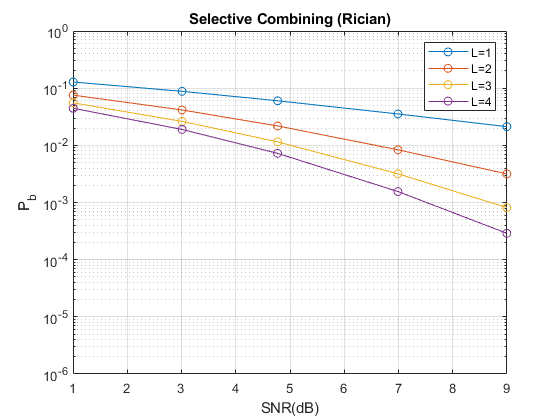

semilogy(10*log10(SNR),P(2,:),'-o')
semilogy(10*log10(SNR),P(3,:),'-o')
semilogy(10*log10(SNR),P(4,:),'-o')
grid
ylim([10^-6,1])
title('Selective Combining (Rician)')
xlabel('SNR(dB)')
ylabel('P_b')
legend('L=1','L=2','L=3','L=4')

(b) Maximal Ratio Combining

% gp(i,j,k) : the sum of power gain from path 1 to path i with SNR=SNR(j) at k-th sample
gp=zeros(L,J,N);
for l=1:L
    for j=1:J
        for k=1:N
            gp(l,j,k)=sum(a([1:l],j,k).^2);
        end        
        P(l,j)=sum(P_b(gp(l,j,:)*SNR(j)))/N;
    end  
end
figure 
semilogy(10*log10(SNR),P(1,:),'-o')
hold

Current plot held


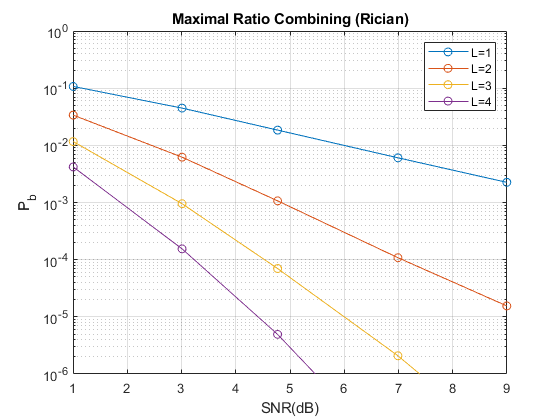

semilogy(10*log10(SNR),P(2,:),'-o')
semilogy(10*log10(SNR),P(3,:),'-o')
semilogy(10*log10(SNR),P(4,:),'-o')
grid
ylim([10^-6,1])
title('Maximal Ratio Combining (Rician)')
xlabel('SNR(dB)')
ylabel('P_b')
legend('L=1','L=2','L=3','L=4')

(c) Equal Gain Combining

% ge(i,j,k) : the sum of energy gain from path 1 to path i with SNR=SNR(j) at k-th sample
ge=zeros(L,J,N);
for l=1:L
    for j=1:J
        for k=1:N
            ge(l,j,k)=sum(a([1:l],j,k));
        end        
        P(l,j)=sum(P_b(ge(l,j,:).^2*SNR(j)/l))/N;
    end  
end
figure 
semilogy(10*log10(SNR),P(1,:),'-o')
hold

Current plot held


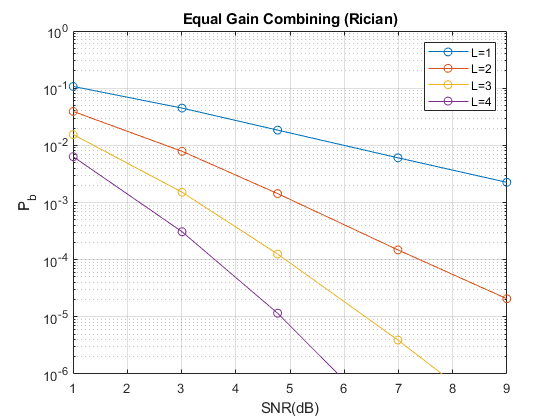

semilogy(10*log10(SNR),P(2,:),'-o')
semilogy(10*log10(SNR),P(3,:),'-o')
semilogy(10*log10(SNR),P(4,:),'-o')
grid
ylim([10^-6,1])
title('Equal Gain Combining (Rician)')
xlabel('SNR(dB)')
ylabel('P_b')
legend('L=1','L=2','L=3','L=4')

(d) Direct Combining

%d(i,j,k) : the sum of a(l,j,k)*phase(l,j,k) from l=1 to i
d=zeros(L,J,N);
for l=1:L
    for j=1:J
        for k=1:N
            d(l,j,k)=sum(a([1:l],j,k).*exp(-i*phase([1:l],j,k)));
        end        
        P(l,j)=sum(P_b(abs(d(l,j,:)).^2*SNR(j)/l))/N;
    end  
end
figure
semilogy(10*log10(SNR),P(1,:),'-o')
hold

Current plot held


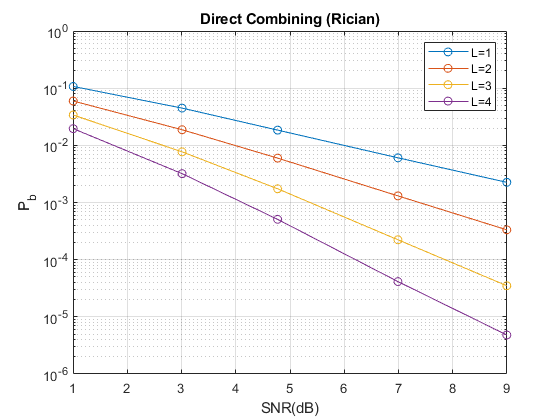

semilogy(10*log10(SNR),P(2,:),'-o')
semilogy(10*log10(SNR),P(3,:),'-o')
semilogy(10*log10(SNR),P(4,:),'-o')
grid
ylim([10^-6,1])
title('Direct Combining (Rician)')
xlabel('SNR(dB)')
ylabel('P_b')
legend('L=1','L=2','L=3','L=4')